global K q Vg n Voc Isc1 T1 Ko S1;
K = 1.381e-23;                      % Boltzmann Constant
q = 1.6e-19;                        % Charge
Vg = 1.12;                          % Band Gap
n = 72;                             % Number of cells
Voc = 44.8;                         % V open circuit
Isc1 = 5.5;                         % Short circuit current STC
T1 = 298;                           % STC tempreature
Ko = 0.00065;                       % Temperature Coefficient
S1 = 1000;                          % Light intensity
VMPP = 36.5;                        % Voltage of max power
IMPP = 5.1;                         % Current at max power
T = 300;                             % temp in kelvin
irrad = 1000 ;                       %irradiance in watt/m2



% Defining the variables for model creation
IL1 = IrradianceCurrent(T1,S1);     % Photonic current in STC

[finaly,finalRs,finalRsh] = modelDesigner(IL1,Voc,VMPP,IMPP) % find the appropriate model

     0



finaly = 1.0200

finalRs = 0.0090

finalRsh = 50

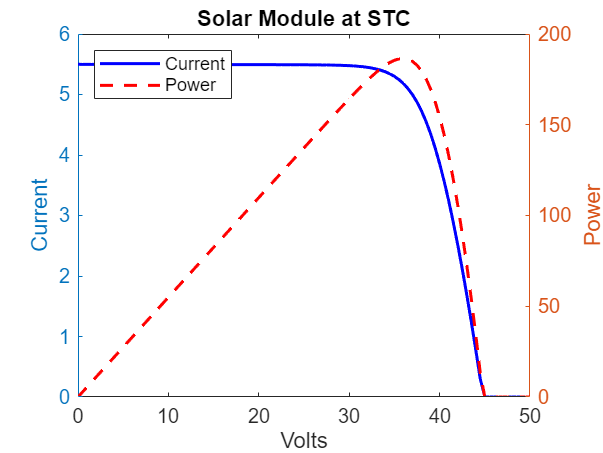


Is1 = ReverseCurrentSTC(finaly);    % Reverse saturation current in STC

%Initializing voltage, current and power values for plotting
V = 0:0.5:50;
outputCurrents = zeros(size(V));
power = zeros(size(V));
% using model parameters for plotting
for i = 1:length(V)
    outputCurrents(i) = currentNewton(IL1,0,Is1,V(i),finalRs,finaly,298,finalRsh);
    power(i) = outputCurrents(i)*(V(i));
end

% Create the plot at STC
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label

% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module at STC');
legend('Current', 'Power', 'Location', 'northwest');

% PVmod function call
voltinp = 25;
irradinp = 1000;
tempinp = 298;
Curr = PVmod(voltinp,irradinp,tempinp,finaly,finalRs,finalRsh)

Curr = 5.4911

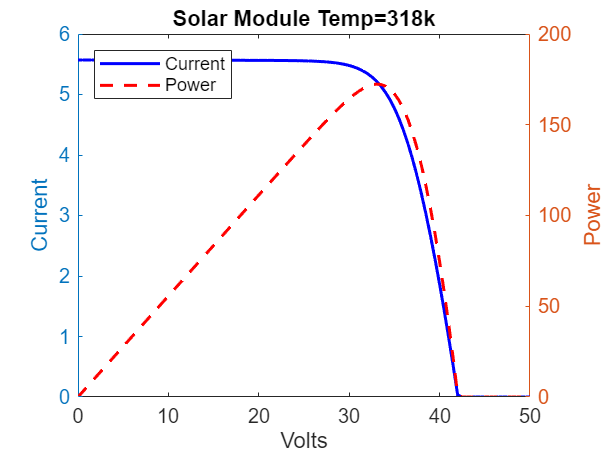

% For different Tempreatures
% IL25 = IrradianceCurrent(298,1000);
IL45 = IrradianceCurrent(318,1000);
IL70 = IrradianceCurrent(343,1000);
IS45 = ReverseCurrent(Is1,318,finaly);
IS70 = ReverseCurrent(Is1,343,finaly);
outputCurrents45 = zeros(size(V));
power45 = zeros(size(V));
outputCurrents70 = zeros(size(V));
power70 = zeros(size(V));
for i = 1:length(V)
    outputCurrents45(i) = currentNewton(IL45,0,IS45,V(i),finalRs,finaly,318,finalRsh);
    outputCurrents70(i) = currentNewton(IL70,0,IS70,V(i),finalRs,finaly,343,finalRsh);
    power45(i) = outputCurrents45(i)*(V(i));
    power70(i) = outputCurrents70(i)*(V(i));;
end
% Create the plot for Temperature of 45 degrees celsius
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents45, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label

% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power45, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module Temp=318k');
legend('Current', 'Power', 'Location', 'northwest');

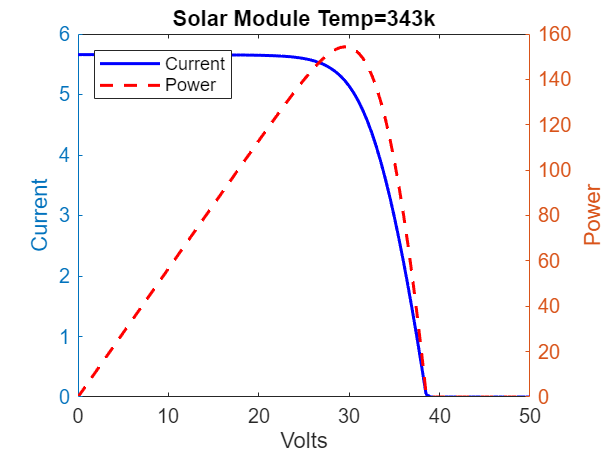



% Create the plot for Temperature of 70 degrees celsius
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents70, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label

% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power70, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module Temp=343k');
legend('Current', 'Power', 'Location', 'northwest');

% For different Irradiances
IL650 = IrradianceCurrent(T1,650);
IL300 = IrradianceCurrent(T1,300);
IS650 = ReverseCurrent(Is1,T1,finaly);
IS300 = ReverseCurrent(Is1,T1,finaly);
outputCurrents650 = zeros(size(V));
power650 = zeros(size(V));
outputCurrents300 = zeros(size(V));
power300 = zeros(size(V));
for i = 1:length(V)
    outputCurrents650(i) = currentNewton(IL650,0,IS650,V(i),finalRs,finaly,T1,finalRsh);
    outputCurrents300(i) = currentNewton(IL300,0,IS300,V(i),finalRs,finaly,T1,finalRsh);
    power650(i) = outputCurrents650(i)*(V(i));
    power300(i) = outputCurrents300(i)*(V(i));
end
outputCurrents650

outputCurrents650 =     3.5744    3.5742    3.5741    3.5739    3.5738    3.5737    3.5735    3.5734    3.5732    3.5731    3.5730    3.5728    3.5727    3.5726    3.5724    3.5723    3.5721    3.5720    3.5719    3.5717    3.5716    3.5714    3.5713    3.5712    3.5710    3.5709    3.5707    3.5706    3.5705    3.5703    3.5702    3.5700    3.5699    3.5698    3.5696    3.5695    3.5693    3.5692    3.5691    3.5689    3.5688    3.5686    3.5685    3.5683    3.5681    3.5680    3.5678    3.5676    3.5674    3.5672


outputCurrents300

outputCurrents300 =     1.6497    1.6496    1.6494    1.6493    1.6491    1.6490    1.6489    1.6487    1.6486    1.6485    1.6483    1.6482    1.6480    1.6479    1.6478    1.6476    1.6475    1.6473    1.6472    1.6471    1.6469    1.6468    1.6466    1.6465    1.6464    1.6462    1.6461    1.6460    1.6458    1.6457    1.6455    1.6454    1.6453    1.6451    1.6450    1.6448    1.6447    1.6446    1.6444    1.6443    1.6441    1.6440    1.6438    1.6437    1.6435    1.6434    1.6432    1.6431    1.6429    1.6427


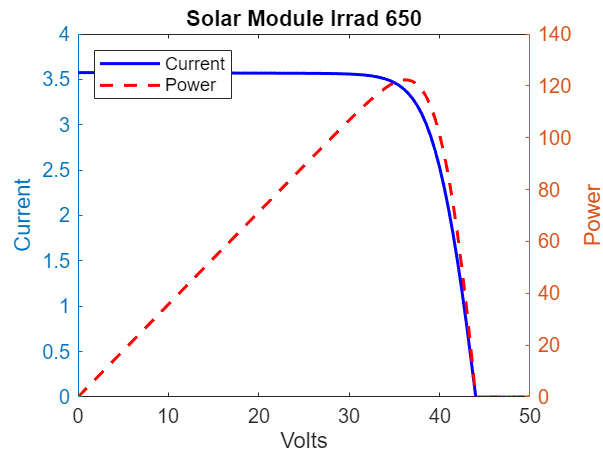

% Create the plot for Irrad 650
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents650, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label
    
% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power650, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module Irrad 650');
legend('Current', 'Power', 'Location', 'northwest');

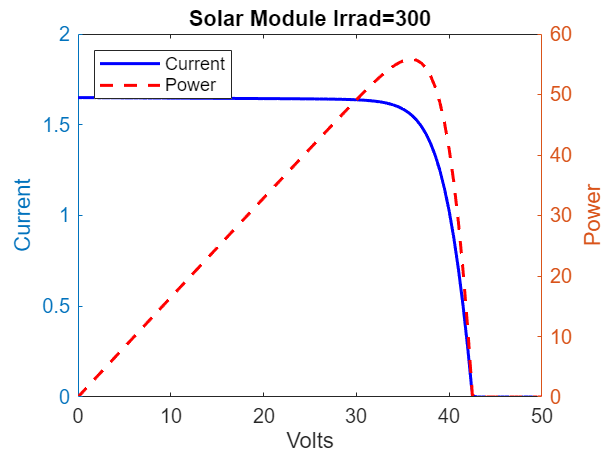



% Create the plot for Irrad 300
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents300, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label

% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power300, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module Irrad=300');
legend('Current', 'Power', 'Location', 'northwest');